# Milling and Welding Todo

Team: Ana Siesto Pérez and Xavier Marti Llull G11-A

Link: [https://drive.matlab.com/sharing/c2cb0355-515d-4b92-8937-bf8df3fe7add](https://drive.matlab.com/sharing/c2cb0355-515d-4b92-8937-bf8df3fe7add) 

See the video: [https://youtu.be/cVZWm9ORY30](https://youtu.be/cVZWm9ORY30)

As you can see in the video a Robot Arm perform three task. Only two tasks are shown: 

- Make a hole in a cylinder by drilling it. Observe that the tool mantain the same orientation during the drilling task.

- Insertion of a smaller cylinder not recorder here. 

- Welding the two cylinder. Observe that the tool always form a 45º with respect to  red cylinder axis

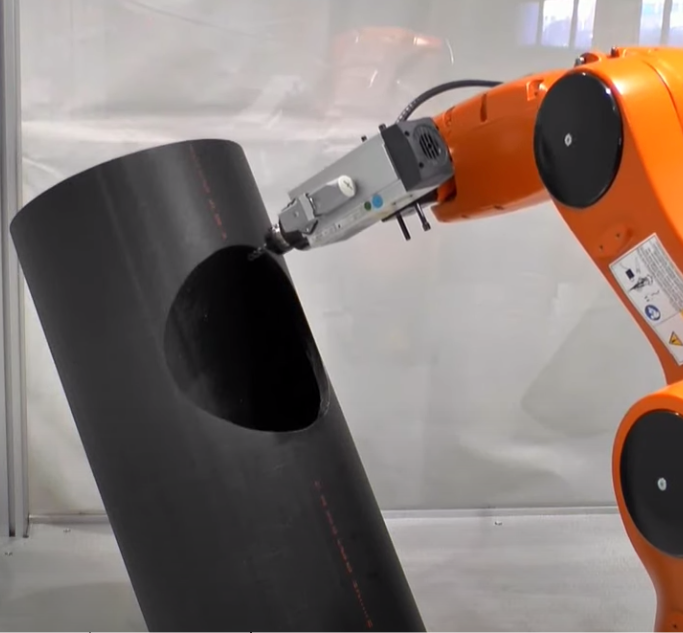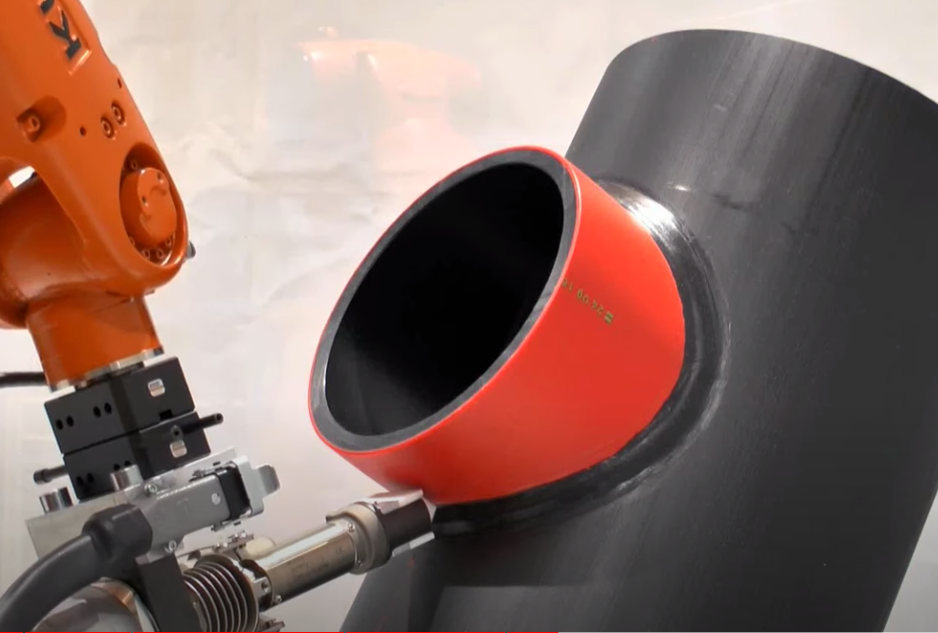

## **Plotting the robot to initial position**

mdl_puma560
p560.tool=transl(0,0,0.15)
p560.plot(qn,'zoom',2.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],'view',[20 20] );
hold on

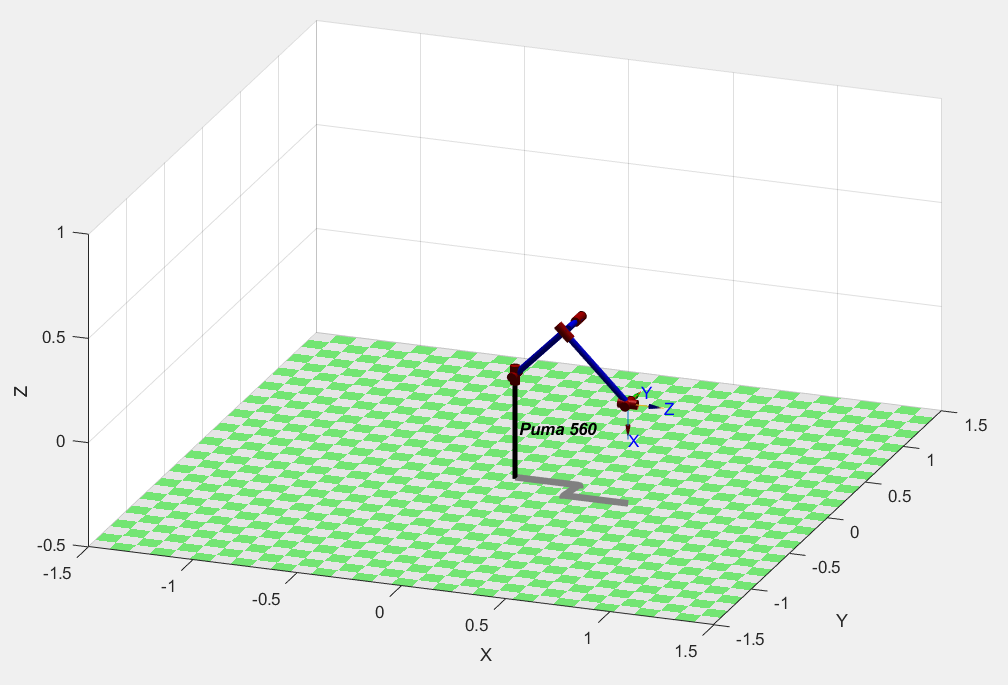

## Constructing the welding zone

(Based on reference frames from figure 6_Hint_cue_for welding task)

### Positioning a frame of reference on our welding region's center

% We've chosen a radius=0.25 and placed our weling region's center in
% (0.5,0.5,0.0).

radi=0.25;
reference_frame=transl(0.5,0.5,0.0)*trotz(-pi/4)*trotx(pi/4)
trplot(reference_frame, 'length',0.2)

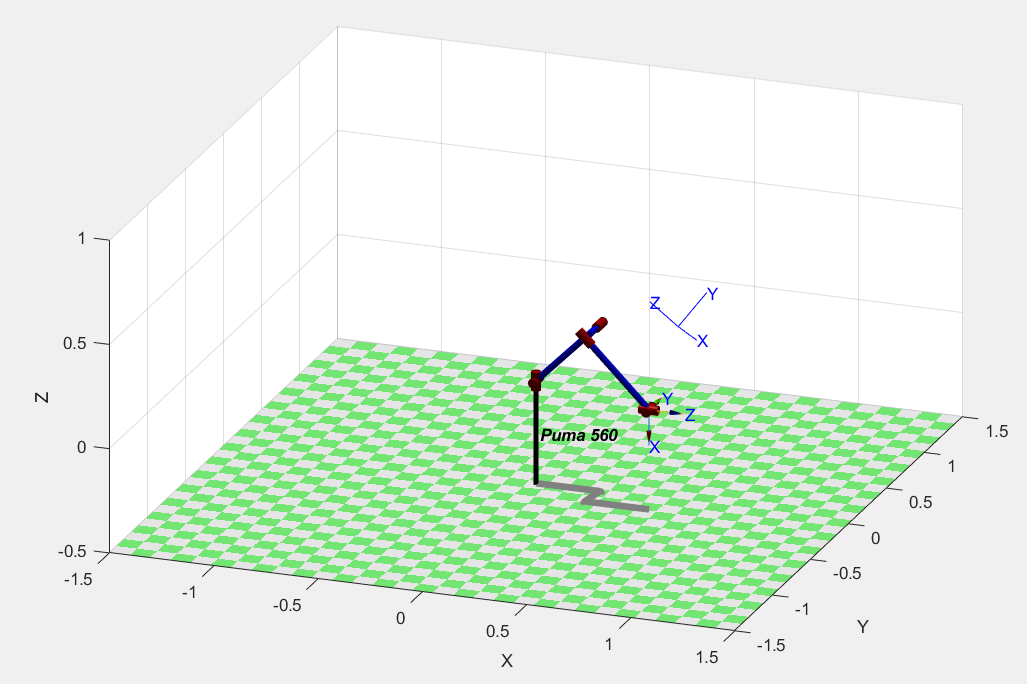

### Acquiring weld (x,y,z) positions and giving orientation to end effector

% We displace the points to be painted to (0.5,0.5,0.0) and then we 
% orient them so they will be placed correctly to weld the tube. After
% that, we take advantage of function [r*cos(a);r*sin(a);abs(r*cos(a))]
% (which describes the welding trajectory) to finally place the points 
% well and at last, we rotate its reference frames in a way that only
% applying trotz(2*pi*i/100)*trotx(-135*pi/180) we will always have the z
% axis forming a 45 degree angle with respect to the z axis from the
% reference frame placed before in the center of the two ortogonal
% intersecting cylinders.

for i=1:100
    Weld_Pos(:,:,i)= transl(0.5,0.5,0.0)*trotz(pi/4)*troty(-pi/4)*...
                     [1 0 0 radi*cos(2*pi*i/100);0 1 0 radi*sin(2*pi*i/100);...
                     0 0 1 abs(radi*cos(2*pi*i/100));0 0 0 1]*trotz(pi/2)*...
                     trotz(2*pi*i/100)*trotx(-135*pi/180)
end

### Plotting the trajectory to be followed with end efector's reference frame examples

cir=transl(Weld_Pos)'
plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);

axis equal
trplot(Weld_Pos(:,:,1), 'length',0.2)
trplot(Weld_Pos(:,:,25), 'length',0.2)
trplot(Weld_Pos(:,:,50), 'length',0.2)
trplot(Weld_Pos(:,:,75), 'length',0.2)

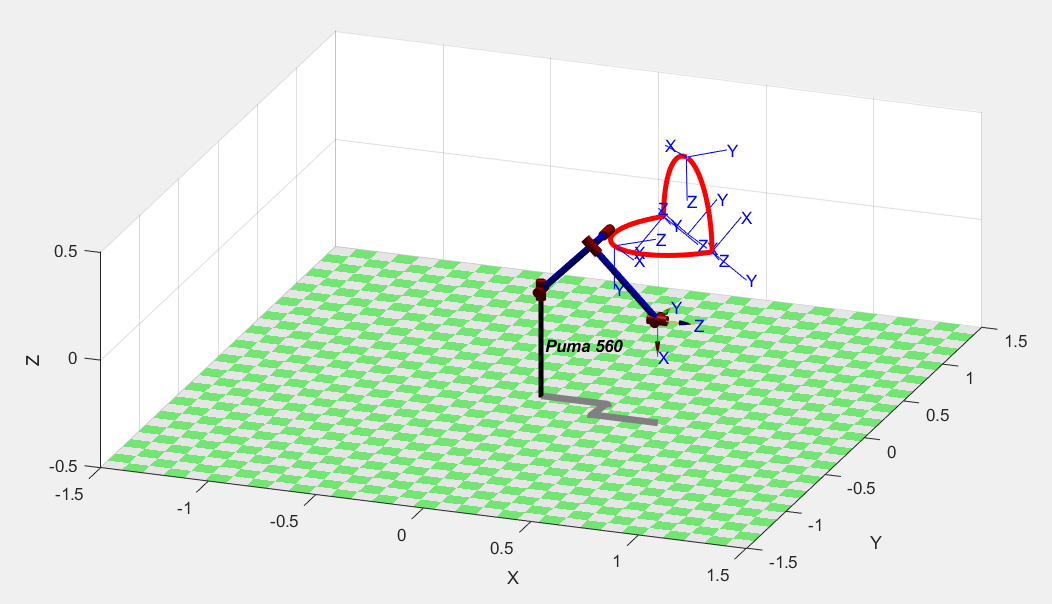

## Using inverse kinematics to plot robot's pose in all the trajectory

Q= p560.ikine6s(Weld_Pos, 'run');
p560.plot(Q,'view',[20 20], 'zoom',1.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],...
    'trail','-','jaxes','zoom',2)